# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_slcm.mlx
    ------------
    This code solves firm's investment problem.

%}

## Model: Model of Firm Investment.

The representative firm is infinitely lived. It maximizes the present value of its lifetime profit by choosing capital investment subject to a convex cost of adjustment. The dynamic programming problem associated with this is:


$$V(A,K,p) = \underset{i}{\text{max}} \ AK^{\alpha} - \frac{\gamma}{2}\left(\frac{i}{K}\right)^2K - pi + \beta \mathbb{E}\left[V(A',K',p)\right] \ ,$$



$$\text{s.t. } \ \text{log} \ A' = \mu + \rho \ \text{log} \ A + \epsilon' \ ,$$



$$K' = (1-\delta)K + i  \ , $$


where $p$ is the price of investment, $|\rho|<1$ and $\epsilon'\sim\mathcal{N}(0,\sigma^2)$. Substituting the law of motion gives


$$V(A,K,p) = \underset{K'}{\text{max}} \ AK^{\alpha} - \frac{\gamma}{2}\left(\frac{K' - (1-\delta)K}{K}\right)^2K - p(K' - (1-\delta)K) + \beta \mathbb{E}\left[V(A',K',p)\right] \ ,$$



$$\text{s.t. } \ \text{log} \ A' = \mu + \rho \ \text{log} \ A + \epsilon' \ .$$


## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

## Set the parameters and generate the state space.

Calls: model.m.

The grid for assets is set exogenously.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Value Function iteration.

Calls: solve.m and model.m.

We will solve the model using value function iteration. Our guess is that firm value is zero over the state space.


$$V(A,K) = 0 \ .$$


t = cputime;
sol = solve.firm_problem(par); % Solve the model using Value Function Iteration.

------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.
Iteration: 300.
Iteration: 325.
Iteration: 350.
Iteration: 375.
Iteration: 400.

Converged in 400 iterations.

------------End of Value Function Iteration.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 7.6700 seconds.


## Simulate the model and plot the policy functions.

Calls: simulate.m and my_graph.m.

Simulate a single firm over time.

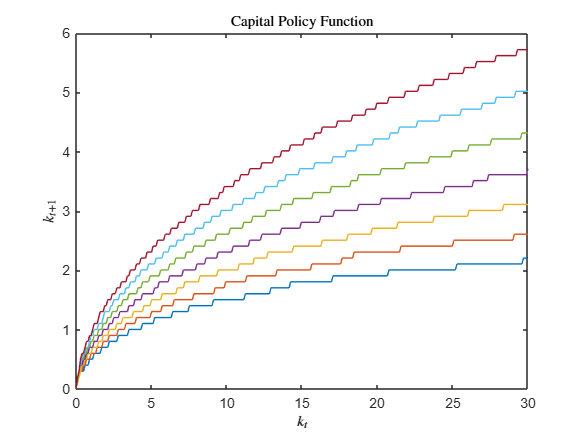

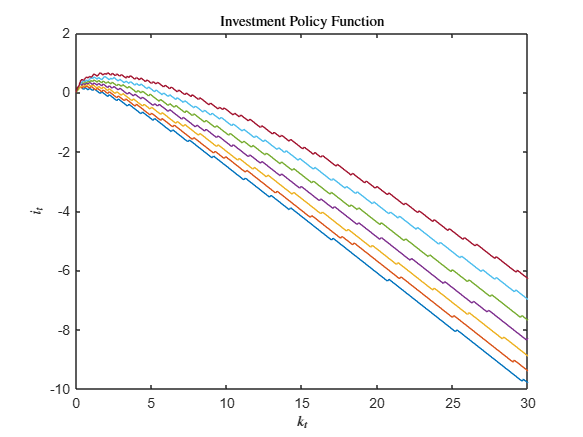

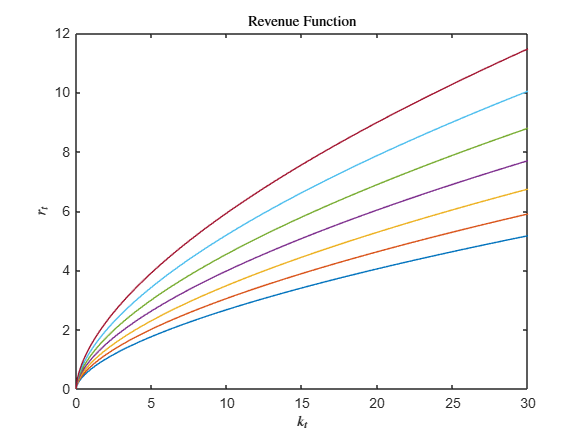

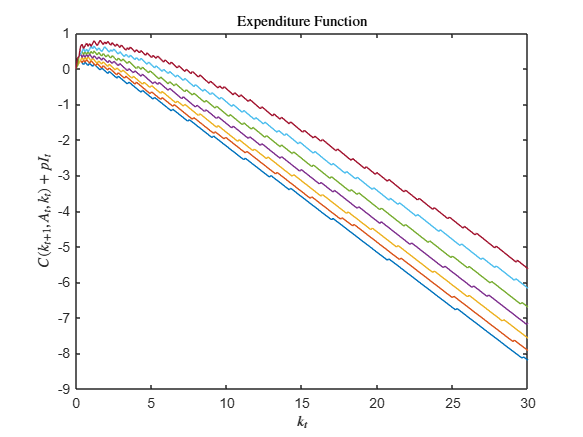

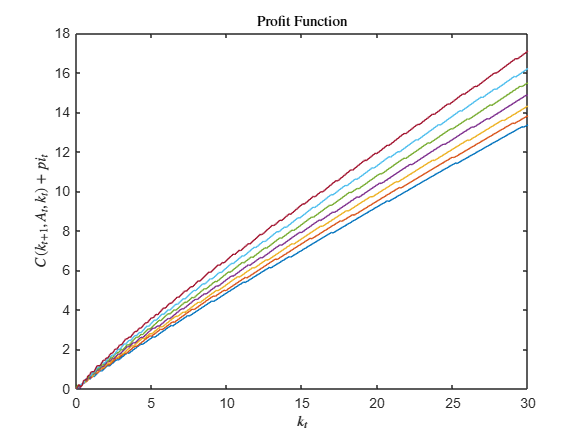

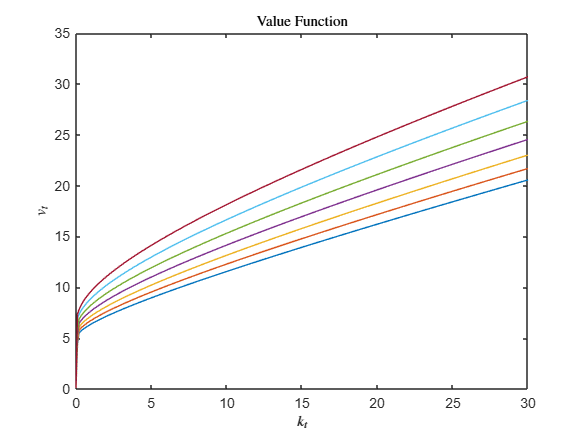

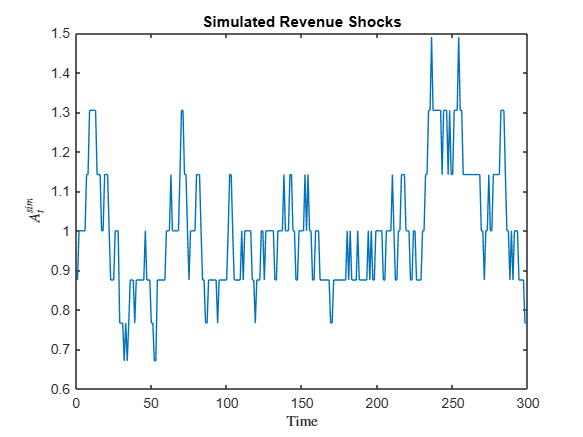

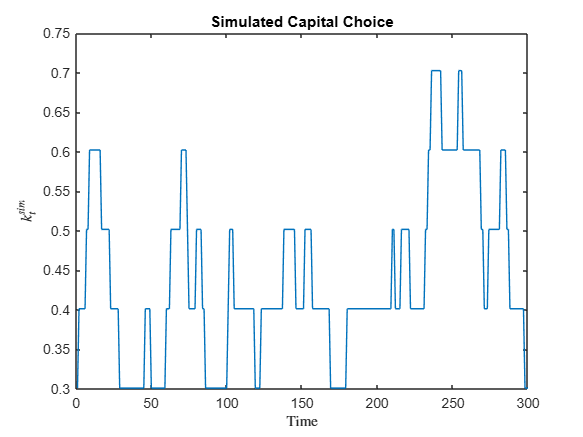

sim = simulate.firm_dynamics(par,sol); % Simulate the model.
my_graph.plot_policy(par,sol,sim) % Plot the model functions and time series.